clear;
clc;

## Formulation

% LB = [-5;-3]; %Lower Bounds
% UB = [1;3]; %Upper Bounds

LB = [-1;-inf]; %Lower Bounds
UB = [1;inf]; %Upper Bounds

X0 = [3.5;1.5]; %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 100000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

## Solve NLP

[X, Cost] = fmincon(@(x) objective(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) constraints(x), options);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3   -2.500000e-01     1.500e+00     1.000e+00     0.000e+00     1.000e+00  
    1           6   -2.560000e+00     4.000e-02     1.000e+00     1.118e+00     3.300e+00  
    2           9   -3.841600e+00     4.000e-02     1.000e+00     4.118e-01     1.480e+00  
    3          12   -4.000000e+00     1.110e-16     1.000e+00     4.000e-02     8.431e-02  
    4          15   -4.000000e+00     0.000e+00     1.000e+00     1.110e-16     3.553e-15  

Optimization completed: The relative first-order optimality measure, 8.881784e-16,
is less than 


disp(X);

    1.0000
    0.0000



disp(Cost);

    -4



## Plot

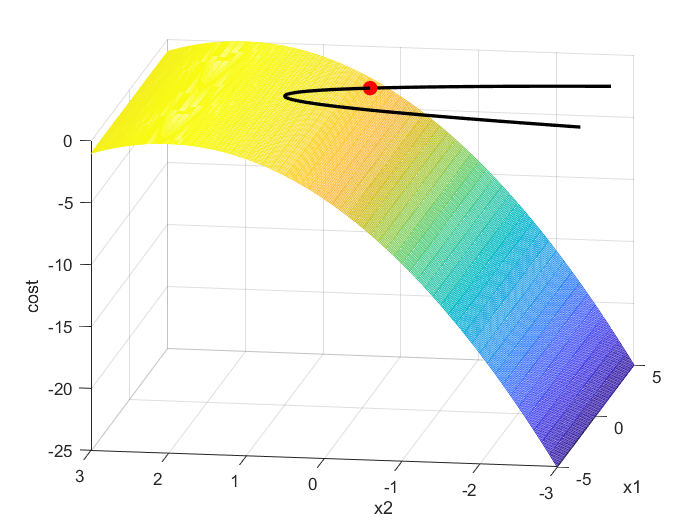

% [x1, x2] = meshgrid(-5:0.1:1, -3:0.1:3);
[x1, x2] = meshgrid(-5:0.1:5, -3:0.1:3);

% cost = sin(x1) + 0.1*x2.^2 + 0.05*x1.^2;
cost = -(x2-2).^2;

figure(1);
% contour(x1, x2, cost, 20, 'LineWidth', 2);
mesh(x1, x2, cost);
xlabel('x1');
ylabel('x2');
zlabel('cost');

% x = -5:0.1:1;
% y = (x+3).^3;
x = -5:0.1:5;
y = 1-x.^2;

hold on;

plot(x, y, 'k', 'LineWidth', 2);
% xlim([-5 1]);
xlim([-5 5]);
ylim([-3 3]);

plot(X(1), X(2), 'r.', 'MarkerSize', 30);